# Constraint-based modelling concepts

**Note: This tutorial is a draft and needs completion. Contributions welcome!**

## Author(s): Ronan Fleming 

## Reviewer(s): 

## INTRODUCTION

*The purpose of the introduction is to enable readers to make a decision as to the suitability of the protocol to their problem. Initially you should introduce the technique under discussion. Include references to key papers where the protocol has been used previously, including those published by your own group or to reviews that discuss applications of the technique (see below for how to cite references).*

## PROCEDURE

Create a simple model. 

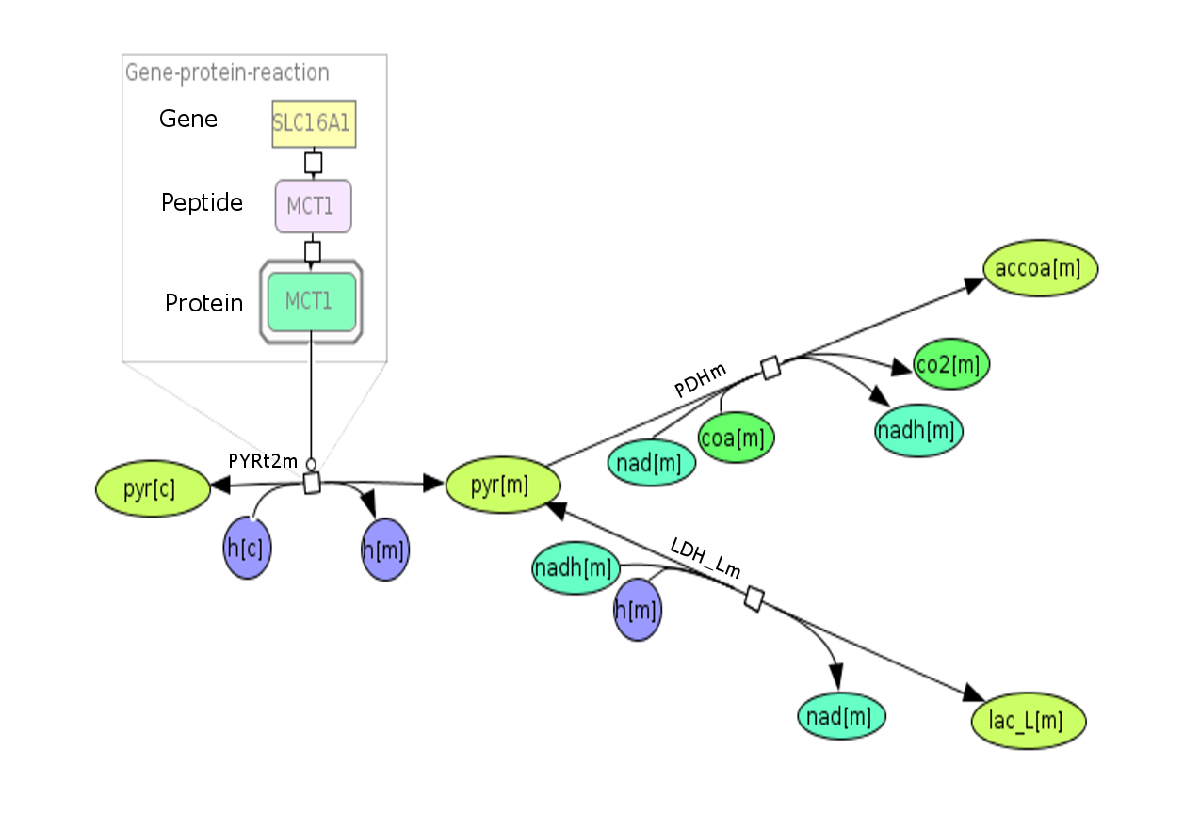

Reaction formulas are given as metabolites and their stoichiometric coefficient concatenated by +. Products and substrates are separated by a reversibility indicator, with `->` indicating an irreversible reaction and `<=>` indicating a reversible reaction.

The reactions are:

[Pyruvate mitochondrial transport via proton symport ](https://vmh.uni.lu/#reaction/PYRt2m)

PYRt2m = 'h[c] + pyr[c] <=> h[m] + pyr[m]'

PYRt2m = h[c] + pyr[c] <=> h[m] + pyr[m]

[Pyruvate dehydrogenase](https://vmh.uni.lu/#reaction/PDHm)

PDHm = 'nad[m] + pyr[m] + coa[m] -> nadh[m] + co2[m] + accoa[m] '

PDHm = nad[m] + pyr[m] + coa[m] -> nadh[m] + co2[m] + accoa[m] 

[L-lactate dehydrogenase](https://vmh.uni.lu/#reaction/LDH_Lm)

LDH_Lm = 'nad[m] + lac_L[m] <=> h[m] + nadh[m] + pyr[m]'

LDH_Lm = nad[m] + lac_L[m] <=> h[m] + nadh[m] + pyr[m]

To be able to use `createModel` to build this model, we also have to define the reaction Identifiers and the reaction names:

reactionIdentifiers = {'PYRt2m', 'PDHm', 'LDH_Lm'}

reactionIdentifiers =     'PYRt2m'    'PDHm'    'LDH_Lm'

reactionNames = {'Pyruvate mitochondrial transport via proton symport ',...
    'Pyruvate dehydrogenase', 'L-lactate dehydrogenase'}

reactionNames =     'Pyruvate mitochondrial transport via proton symport '    'Pyruvate dehydrogenase'    'L-lactate dehydrogenase'

And we have to combine the reactions:

reactionFormulas = {PYRt2m, PDHm, LDH_Lm}

reactionFormulas =     'h[c] + pyr[c] <=> h[m] + pyr[m]'    'nad[m] + pyr[m] + coa[m] -> nadh[m] + co2[m] + accoa[m] '    'nad[m] + lac_L[m] <=> h[m] + nadh[m] + pyr[m]'

Now we can call

model = createModel(reactionIdentifiers, reactionNames, reactionFormulas);

PYRt2m	h[c] + pyr[c] 	<=>	h[m] + pyr[m] 


PDHm	pyr[m] + nad[m] + coa[m] 	<=>	nadh[m] + co2[m] + accoa[m] 


LDH_Lm	nad[m] + lac_L[m] 	<=>	h[m] + pyr[m] + nadh[m] 


The reactions are:

v1 = ' <=> A'

v1 =  <=> A

v2 = 'A <=> B'

v2 = A <=> B

v3 = 'A <=> C'

v3 = A <=> C

v4 = 'B <=> C'

v4 = B <=> C

v5 = 'C <=> '

v5 = C <=> 

v6 = 'B <=> '

v6 = B <=> 

To be able to use `createModel` to build this model, we also have to define the reaction Identifiers and the reaction names:

reactionIdentifiers = {'v1', 'v2', 'v3', 'v4', 'v5', 'v6'}

reactionIdentifiers =     'v1'    'v2'    'v3'    'v4'    'v5'    'v6'

reactionNames = {'v1', 'v2', 'v3', 'v4', 'v5','v6'}

reactionNames =     'v1'    'v2'    'v3'    'v4'    'v5'    'v6'

And we have to combine the reactions:

reactionFormulas = {v1, v2, v3, v4, v5, v6}

reactionFormulas =     ' <=> A'    'A <=> B'    'A <=> C'    'B <=> C'    'C <=> '    'B <=> '

Now we can call

model = createModel(reactionIdentifiers, reactionNames, reactionFormulas,'lowerBoundList',[-100 -100 -100 -100 -100 -100],'upperBoundList',[100 100 100 100 100 100]);

v1		<=>	A[c] 


v2	A[c] 	<=>	B[c] 


v3	A[c] 	<=>	C[c] 
v4	B[c] 	<=>	C[c] 
v5	C[c] 	<=>	
v6	B[c] 	<=>	


Now we plot the reaction rates of v3,v4,v5:

bool=logical([0;0;1;1;1;0]);
model.S=full(model.S);
model.S(:,bool)

ans =     -1     0     0
     0    -1     0
     1     1    -1

%function plotregion(A,b,lb,ub,c,transp,points,linetyp,start_end)
% The function plotregion plots closed convex regions in 2D/3D. The region
% is formed by the matrix A and the vectors lb and ub such that Ax>=b
% and lb<=x<=ub, where the region is the set of all feasible x (in R^2 or R^3).
% An option is to plot points in the same plot.
%
% Usage:   plotregion(A,b,lb,ub,c,transp,points,linetyp,start_end)
%
% Input:
%
% A - matrix. Set A to [] if no A exists
% b - vector. Set b to [] if no b exists
% lb - (optional) vector. Set lb to [] if no lb exists
% ub - (optional) vector. Set ub to [] if no ub exists
% c - (optional) color, example 'r' or [0.2 0.1 0.8], {'r','y','b'}.
%       Default is a random colour.
% transp - (optional) is a measure of how transparent the
%           region will be. Must be between 0 and 1. Default is 0.5.
% points - (optional) points in matrix form. (See example)
% linetyp - (optional) How the points will be marked.
%           Default is 'k-'.
% start_end - (optional) If a special marking for the first and last point
%              is needed.
%
% If several regions must be plotted A ,b, lb, ub and c can be stored as a cell array {}
% containing all sub-set information (see example1.m and example3.m). 
%
% Written by Per Bergstrm 2006-01-16
c=[0.1,0.9,0.0];
transp=0.5;
%points
%linetyp
%start_end

No constraints

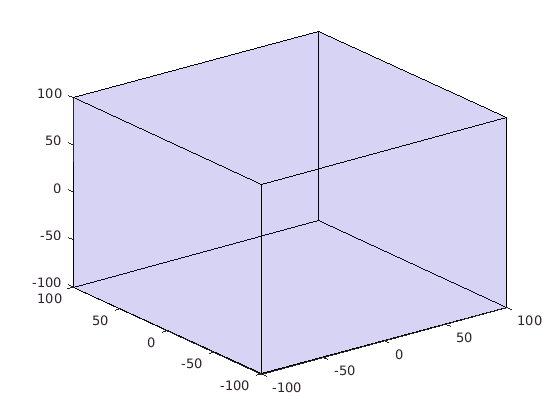

figure;
plotregion([],[],model.lb(bool),model.ub(bool),[0.2 0.1 0.8],0.1)

Inequality

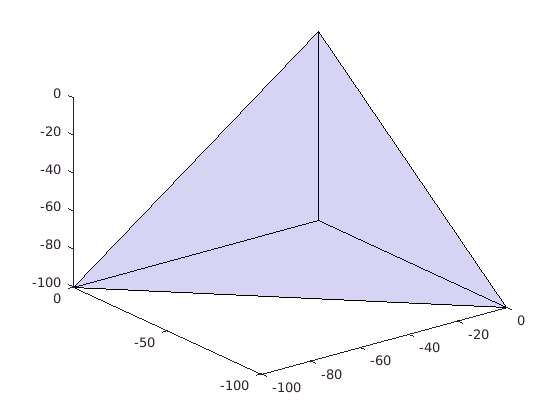

figure;
A=model.S(:,bool);
b=[0;0;0];
plotregion(A,b,model.lb(bool),model.ub(bool),[0.2 0.1 0.8],0.1)

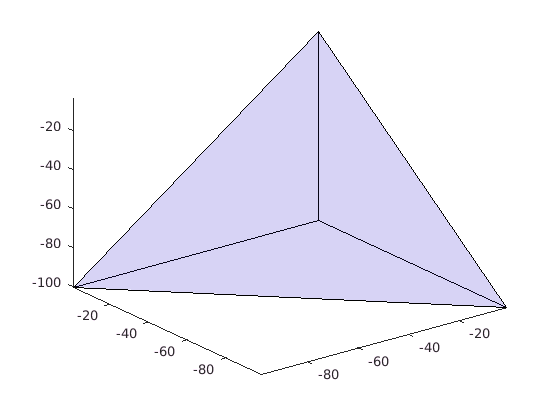

figure;
A=[model.S(:,bool);model.S(:,bool)];
b0=[0;0;0];
b=[b0-1;b0+1];
plotregion(A,b,model.lb(bool),model.ub(bool),[0.2 0.1 0.8],0.1)

figure;
plotregion([model.S(:,bool);-model.S(:,bool)],[0;0],model.lb(bool)*0,model.ub(bool),[0.2 0.1 0.8],0.1)

return
A=[model.S;-model.S];
b=[model.b;model.b];

figure;
plotregion(A,b,model.lb,model.ub,c,transp);%,points,linetyp,start_end)

*Step by step methodology. This is the key section of the tutorial and must be a direct instructions. Use the active tense rather than the passive tense, for example, "Run flux balance analysis", instead of "Flux balance analysis was run". If the protocol naturally breaks into separate stages, then include subheadings and resume the numbered list. Include a TIMING callout with each subheading and state how long the section will take to complete. *

*Highlight critical steps in the protocol that must be performed in a very precise manner e.g., where the input is crucial or the checking of computational solutions against the literature is required; thus providing the user with hints to maximize the likelihood of success. Make these clear with the heading ‘CRITICAL STEP’, followed by a brief explanation.  Include diagrams where appropriate. If the tutorial is complicated you should consider including a flow diagram to demonstrate how the stages fit together. *

*Where there are alternative routes to reach the next stage of the protocol, please give enough background so that the reader will be able to make an informed decision on the route to choose. Letters of the Latin alphabet (A), B), C)...) should be used to identify the different options, and Roman numerals (i), ii), etc.) should be used to break down the appropriate steps.*

*1. This step can be performed using option A or option B depending on whether...*

*A. First option*

*i. First part*

*ii. Second part, etc.*

*B. Second option*

*i. First part*

*ii. Second part, etc.*

*If you wish to include subheadings, add the subheading at the start of the first step within that section and make the text italic. This formatting can also be used to include second level subheadings within the main procedure.*

## TROUBLESHOOTING

*Please include TROUBLESHOOTING callouts after steps where problems are encountered. Include full details of the problem and solutions in a later Troubleshooting section. *

## TIMING

*If possible, please include a timeline indicating the approximate time a step, or set of steps, will take e.g. Steps 1–3, 30 min.; Steps 6+7, 2 h. Provide this information as a summary at the end of the procedure, as a list. If you think it would be more user friendly you could refer to time needed for each section or detail what needs to be performed on each day of the protocol.*

## *TROUBLESHOOTING*

*After key steps, include information on how to troubleshoot the most likely problems users will encounter with the tutorial. Ideally provide this information in the form ‘problem’, ‘possible reason’, ‘solution’. *

## ANTICIPATED RESULTS

*Include information about, or examples of, the likely outcome to users, for example, likely solution to an optimisation problem, etc. Include example that works very well and a second for that requires troubleshooting to obtain meaningful results. If not described in detail in the introduction, this is a good place to include directions on how to interpret and analyze the computational results including equations if necessary.*

## *Acknowledgments*

*Please note an acknowledgments section can be included.*

## REFERENCES

*plotregion.m by Per Bergstrom *[https://nl.mathworks.com/matlabcentral/fileexchange/9261-plot-2d-3d-region](https://nl.mathworks.com/matlabcentral/fileexchange/9261-plot-2d-3d-region)

*List all references mentioned in the protocol. References are numbered sequentially as they appear in the text, figure legends, tables and boxes. Use superscript numbers to indicate a reference, for example 1 . Only one publication is given for each number, and footnotes are not used. Only papers that have been published or accepted by a named publication should be in the numbered list; meeting abstracts and papers in preparation should be mentioned in the text with a list of authors (or initials if any of the authors are co-authors of the present contribution). Patents should be included in the reference list. Published conference abstracts and URLs for web sites should be cited parenthetically in the text, not in the reference list; articles in formal, peer-reviewed online journals should be included in the reference list. Grant details and acknowledgments are not permitted as numbered references.*

*All authors should be included in reference lists unless there are more than five, in which case only the first author should be given, followed by 'et al.'. Authors should be listed last name first, followed by a comma and initials of given names. Titles of cited articles are required and should be in Roman text and titles of books in italics; the first word of the title is capitalized, the title written exactly as it appears in the work cited, ending with a period. Journal names are italicized and abbreviated (with periods) according to common usage; refer to the National Library of Medicine for details. Volume numbers appear in bold. For book citations, the publisher and city of publication are required (e.g. John Wiley & Sons,  Hoboken, New Jersey, USA, 2003). *

*List all references mentioned in the protocol. Use the format given in the examples below:*

*3. Helms, C. et al. A putative RUNX1 binding site variant between SLC9A3R1 and RAT9 is associated with susceptibility to psoriasis. Nat. Genet. 35, 349-356 (2003).*

*4. Lovett, M. Direct selection of cDNAs with large genomic DNA clones. InMolecular Cloning: A Laboratory Manual Edn. 3 Vol. 2 (eds. Sambrook., J. & Russell, D.W.) 11.98-11.133 (Cold Spring Harbor Laboratory Press, Cold Spring Harbor, New York, USA, 2001).*

*5. Petroff, M.D. & Stapelbroek, M.G. Blocked impurity band detectors. US Patent 4,586,960 filed 23 Oct. 1980, and issued 4 Feb. 1986.*